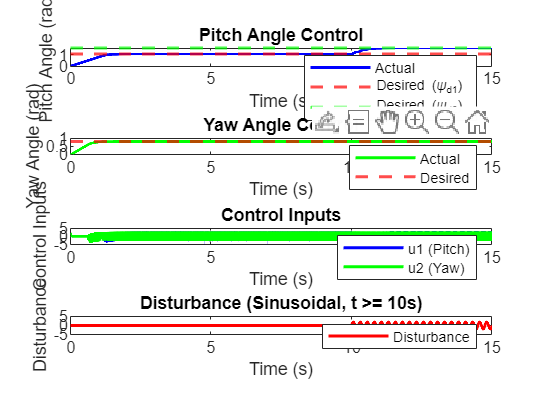

% Sliding Mode Control for Twin Rotor MIMO System
clc;
clear;
close all;

%% System Parameters (example values; replace with actual parameters)
I1 = 0.05;         % Moment of inertia around pitch axis
I2 = 0.04;         % Moment of inertia around yaw axis
a1 = 0.1;          % Nonlinear coefficient for pitch motor
b1 = 0.02;         % Linear coefficient for pitch motor
a2 = 0.1;          % Nonlinear coefficient for yaw motor
b2 = 0.02;         % Linear coefficient for yaw motor
Ms = 0.01;         % Gravity torque coefficient
B1_psi = 0.01;     % Linear friction coefficient for pitch
B2_psi = 0.01;     % Nonlinear friction coefficient for pitch
B1_phi = 0.01;     % Linear friction coefficient for yaw
B2_phi = 0.01;     % Nonlinear friction coefficient for yaw
Kg = 0.001;        % Gyroscopic torque coefficient
Kr = 0.005;        % Cross-coupling coefficient
Ts = 0.1;          % Time constant for cross-reaction

% Desired angles (step input for psi_d and constant phi_d)
psi_d1 = pi / 3;    % Initial desired pitch angle (20 degrees)
psi_d2 = pi / 2;    % Final desired pitch angle (30 degrees)
phi_d = pi / 4;     % Desired yaw angle (45 degrees)

% Sliding surface parameters
lambda_psi = 5;    % Sliding surface gain for pitch
lambda_phi = 5;    % Sliding surface gain for yaw
k_psi = 2;         % Sliding mode gain for pitch
k_phi = 2;         % Sliding mode gain for yaw
epsilon = 0.01;    % Smoothing factor for sat() function

% Disturbance parameters
disturbance_amplitude = 2;
disturbance_frequency = 4; % Hz

%% Simulation Parameters
dt = 0.001;        % Time step
t_final = 15;      % Extended simulation duration
time = 0:dt:t_final;

% State initialization
psi = 0;           % Initial pitch angle
phi = 0;           % Initial yaw angle
psi_dot = 0;       % Initial pitch angular velocity
phi_dot = 0;       % Initial yaw angular velocity

% State history for plotting
psi_history = zeros(size(time));
phi_history = zeros(size(time));
u1_history = zeros(size(time));
u2_history = zeros(size(time));
disturbance_history = zeros(size(time));

%% Main Simulation Loop
for i = 1:length(time)
    t = time(i);
    
    % Step input for psi_d
    if t < 10
        psi_d = psi_d1;
    else
        psi_d = psi_d2;
    end
    
    % Add disturbance after t >= 10 seconds
    if t >= 10
        disturbance = disturbance_amplitude * sin(2 * pi * disturbance_frequency * (t - 10));
    else
        disturbance = 0;
    end

    % Sliding surfaces
    s_psi = psi_dot + lambda_psi * (psi - psi_d);
    s_phi = phi_dot + lambda_phi * (phi - phi_d);

    % Equivalent control: Pitch (u1)
    M_1 = a1 * (psi_dot)^2 + b1 * psi_dot;
    M_FG = Ms * sin(psi);
    M_BV = B1_psi * psi_dot + B2_psi * sin(psi_dot);
    M_G = Kg * M_1 * phi_dot * cos(psi);
    tau_1_eq = (I1 * (-lambda_psi * psi_dot - M_FG - M_BV - M_G)) / a1;

    % Equivalent control: Yaw (u2)
    M_2 = a2 * (phi_dot)^2 + b2 * phi_dot;
    M_Bphi = B1_phi * phi_dot + B2_phi * sin(phi_dot);
    M_R = Kr * psi_dot / (Ts + psi_dot);
    tau_2_eq = (I2 * (-lambda_phi * phi_dot - M_Bphi - M_R)) / a2;

    % Sliding mode control with sat() for pitch and yaw
    u1 = tau_1_eq - k_psi * sat(s_psi / epsilon);
    u2 = tau_2_eq - k_phi * sat(s_phi / epsilon);

    % Add disturbance to the pitch dynamics
    psi_ddot = (1 / I1) * (u1 - M_FG - M_BV - M_G + disturbance);
    phi_ddot = (1 / I2) * (u2 - M_Bphi - M_R);

    % Update dynamics using Euler integration
    psi_dot = psi_dot + psi_ddot * dt;
    phi_dot = phi_dot + phi_ddot * dt;
    psi = psi + psi_dot * dt;
    phi = phi + phi_dot * dt;

    % Save data for plotting
    psi_history(i) = psi;
    phi_history(i) = phi;
    u1_history(i) = u1;
    u2_history(i) = u2;
    disturbance_history(i) = disturbance;
end

%% Plot Results
figure;

subplot(4, 1, 1); % Pitch angle
plot(time, psi_history, 'b', 'LineWidth', 1.5);
hold on;
yline(psi_d1, '--r', 'LineWidth', 1.5);
yline(psi_d2, '--g', 'LineWidth', 1.5);
xlabel('Time (s)');
ylabel('Pitch Angle (rad)');
title('Pitch Angle Control');
legend('Actual', 'Desired (\psi_{d1})', 'Desired (\psi_{d2})');

subplot(4, 1, 2); % Yaw angle
plot(time, phi_history, 'g', 'LineWidth', 1.5);
hold on;
yline(phi_d, '--r', 'LineWidth', 1.5);
xlabel('Time (s)');
ylabel('Yaw Angle (rad)');
title('Yaw Angle Control');
legend('Actual', 'Desired');
ylim([0, 1]);
subplot(4, 1, 3); % Control inputs
plot(time, u1_history, 'b', 'LineWidth', 1.5);
hold on;
plot(time, u2_history, 'g', 'LineWidth', 1.5);
xlabel('Time (s)');
ylabel('Control Inputs');
title('Control Inputs');
legend('u1 (Pitch)', 'u2 (Yaw)');
ylim([-5, 5]); % Adjust scale for better visibility

subplot(4, 1, 4); % Disturbance
plot(time, disturbance_history, 'r', 'LineWidth', 1.5);
xlabel('Time (s)');
ylabel('Disturbance');
title('Disturbance (Sinusoidal, t >= 10s)');
legend('Disturbance');
ylim([-5, 5]);

%% Saturation Function

function out = sat(x)
    if abs(x) <= 1
        out = x;
    else
        out = sign(x);
    end
end
